clear all 
close all
clc

% Load the Normal and Abnormal dataset
normal=readtable('Data_normal.csv');
abnormal=readtable('Data_abnormal.csv');

% Merge the two datasets
data = [normal; abnormal];

% Preview the dataset
head(data);

      angry        disgust        fear       happy        sad        surprise      neutral      Parkinson
    __________    _________    __________    ______    _________    __________    __________    _________

      0.015409     6.87e-06    0.00016371    98.973      0.01357    0.00077458       0.99733        0    
      2.89e-06     7.35e-17      1.44e-09    99.998     6.87e-05    0.00088937    0.00066469        0    
        2.9653       0.2494        4.9925    86.118       5.3456       0.31935      0.010191        0    
      2.22e-08      1.5e-18      5.63e-11    99.987     8.73e-07     0.0022215      0.010645        0    
       0.55809    0.0026221       0.02163    77.139       3.9803     0.0017552        18.29


% Separate the predictors from the target
X = data(:,1:end-1); % all columns except the last one
Y = data.Parkinson; % target column

% Train : Test = 80 :20
cv = cvpartition(size(data,1),'HoldOut',0.2);
idx = cv.test;

% Separate data into training and test sets
XTrain = X(~idx,:);
YTrain = Y(~idx);
XTest  = X(idx,:);
YTest  = Y(idx);

% Train the KNN model
model = fitcknn(XTrain, YTrain, 'NumNeighbors', 3, 'Standardize', 1, 'Distance', 'euclidean');

% Predict the labels and posterior probabilities for the test set
[YPred, YScores] = predict(model, XTest);

% Convert labels in YTest and YPred to numeric values
YPredNum = grp2idx(YPred);
YTestNum = grp2idx(YTest);

% Create a cell array of class labels
classLabels = {'Normal', 'Abnormal'};

% Print the posterior probabilities, predicted class, and actual class for each test sample
for i = 1:size(YScores,1)
    fprintf('\nTest sample %d\n Predicted probabilities: Normal %.2f, Abnormal %.2f\n Predicted class: %s\n Actual class: %s\n', i,YScores(i,1), YScores(i,2),classLabels{YPredNum(i)},classLabels{YTestNum(i)});
end


Test sample 1
 Predicted probabilities: Normal 1.00, Abnormal 0.00
 Predicted class: Normal
 Actual class: Normal

Test sample 2
 Predicted probabilities: Normal 1.00, Abnormal 0.00
 Predicted class: Normal
 Actual class: Normal

Test sample 3
 Predicted probabilities: Normal 1.00, Abnormal 0.00
 Predicted class: Normal
 Actual class: Normal

Test sample 4
 Predicted probabilities: Normal 1.00, Abnormal 0.00
 Predicted class: Normal
 Actual class: Normal

Test sample 5
 Predicted probabilities: Normal 0.67, Abnormal 0.33
 Predicted class: Normal
 Actual class: Normal

Test sample 6
 Predicted probabilities: Normal 1.00, Abnormal 0.00
 Predicted class: Normal
 Actual class: Normal

Test sample 7
 Predicted probabilities: Normal 1.00, Abnormal 0.00
 Predicted class: Normal
 Actual class: Normal

Test sample 8
 Predicted probabilities: Normal 1.00, Abnormal 0.00
 Predicted class: Normal
 Actual class: Normal

Test sample 9
 Predicted probabilities: Normal 1.00, Abnormal 0.00
 Predicted c


% Evaluate the performance
accuracy = sum(YTestNum == YPredNum) / length(YTestNum);
fprintf('\nOverall accuracy: %.2f\n', accuracy * 100);


Overall accuracy: 91.54



% Cross-Validation
cvmodel = crossval(model,'kfold',10);

% Compute validation predictions
YValidationPred = kfoldPredict(cvmodel);

% Compute validation accuracy
valAccuracy = sum(YTrain == YValidationPred) / length(YTrain);
fprintf('\nValidation Accuracy: %.2f\n', valAccuracy * 100);


Validation Accuracy: 90.21


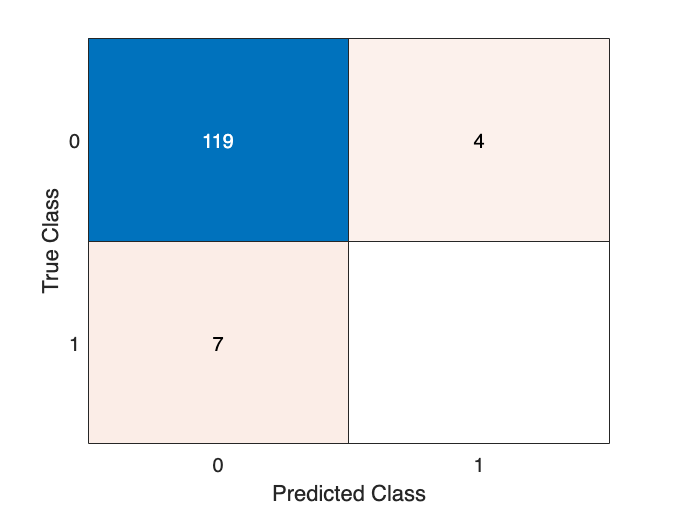


% Generate confusion matrix
figure;
confusionchart(YTest, YPred);